# 1.0 Human vs Machine Learning

Let's take a closer look at the difference between how we learn as humans and how machines learn.

Consider this relation between two variables, $x$ and $y$. 

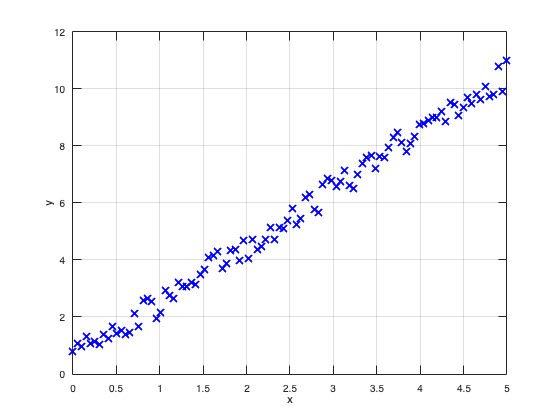

clear; clf; 
m = 2; b = 0.5;
x = linspace(0,5,100);
y = addrandomfluctuations(x,m,b,1);
plot(x,y,'bx','MarkerSize',10, 'LineWidth',2)
xlabel('x'); ylabel('y');
% axis([0 0.5 0 2])
grid on

*Figure 1.1. A data set that forms a straight line. But the computer doesn't know it's a straight line.*

## 1.1 How we determine the best fit line

We know instinctively that this data forms a straight line, even though there's a little bit of randomness in the line. We know that we can plot a straight line that will represent this data. The straight line that fits this data set is given by $y=mx+b$, where $m$ is the slope and $b$ is the y-intercept. We can get the slope and the y-intercept using three methods. The first is we get a ruler and we draw a line that roughly passes through these points. We see that it intersects the y-axis at some point and we call that point our y-intercept. Then, we count the number of grid lines that represents the rise along the y-axis and the run along the x-axis to estimate the slope. The second method is we estimate the error between these data points and the expected value, represented by the equation of a line, and we minimize that error by doing some calculus. Minimizing gives us the slope and the y-intercept. We know this because these are the rules that mathematics taught us. 

Of course, the third method is to use the tools available to us in MATLAB.

p = polyfit(x,y,1)

p =     1.9833    0.5645


ylr = addrandomfluctuations(x,p(1),p(2),0.0)

ylr =     0.5645    0.6646    0.7648    0.8650    0.9651    1.0653    1.1655    1.2656    1.3658    1.4660    1.5661    1.6663    1.7665    1.8666    1.9668    2.0670    2.1671    2.2673    2.3675    2.4676    2.5678    2.6680    2.7682    2.8683    2.9685    3.0687    3.1688    3.2690    3.3692    3.4693    3.5695    3.6697    3.7698    3.8700    3.9702    4.0703    4.1705    4.2707    4.3708    4.4710    4.5712    4.6713    4.7715    4.8717    4.9719    5.0720    5.1722    5.2724    5.3725    5.4727


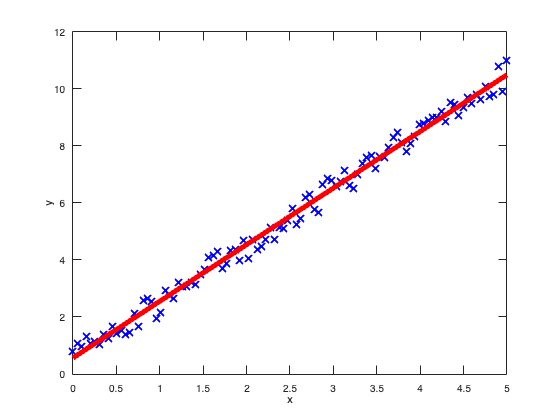


plot(x,y,'bx','MarkerSize',10, 'LineWidth',2)
hold on
plot(x,ylr, 'r', 'LineWidth',5)
xlabel('x'); ylabel('y');
% axis([0 0.5 0 2])
hold off

An alternative solution is shown below using the function fitlm().

% use linear regression to determine the best fit
model = fitlm(x,y)

model = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue   
                   ________    ________    ______    ___________

    (Intercept)    0.56445      0.05789    9.7504     4.2136e-16
    x1              1.9833     0.020003     99.15    4.2604e-100


Number of observations: 100, Error degrees of freedom: 98
Root Mean Squared Error: 0.292
R-squared: 0.99,  Adjusted R-Squared: 0.99
F-statistic vs. constant model: 9.83e+03, p-value = 4.26e-100


% display the computed coefficients
model.Coefficients

ans = 2×4 table
                   Estimate       SE       tStat       pValue   
                   ________    ________    ______    ___________

    (Intercept)    0.56445      0.05789    9.7504     4.2136e-16
    x1              1.9833     0.020003     99.15    4.2604e-100



% extract the slope and yintercept to the variables
yintercept = model.Coefficients.Estimate(1,1)

yintercept = 0.5645

slope = model.Coefficients.Estimate(2,1)

slope = 1.9833

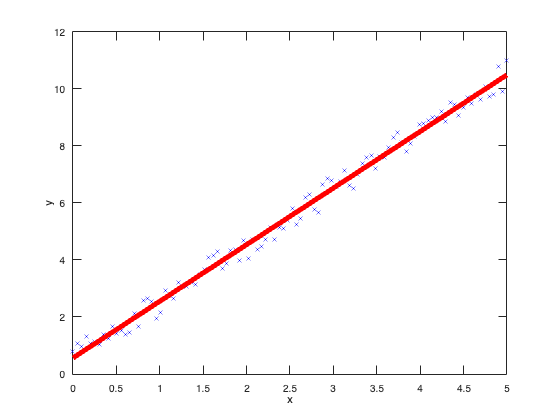


% generate the y data set from linear regression
ylr = model.Fitted;

plot(x,y,'bx','MarkerSize',5)
hold on
plot(x,ylr, 'r', 'LineWidth',5)
xlabel('x'); ylabel('y');
hold off

*Figure 1.2. Predicted best fit line using the linear regression algorithm of MATLAB.*

## 1.2 How a computer determines the best fit line

A computer doesn't know any of these rules. What the computer does after it gets the data is that it'll make several guesses for the slope and the y-intercept until the error becomes really small. In each guess, it rewrites some parameters that it uses so that the error becomes smaller and smaller. When the error is small enough, then the computer returns the final value of the slope and the y-intercept to represent the line. After all of that, the computer still doesn't know what the mathematical rules are.

This short code is a machien learning model that will solve for the best fit line of the given data $x$ and $y$.

% Alternative 1

layers = [
    sequenceInputLayer(1,"MinLength",length(x))
    fullyConnectedLayer(1)
    regressionLayer
    ];
options = trainingOptions("sgdm","MaxEpochs",100,...
    "InitialLearnRate",0.0001,...
    "Plots","training-progress")

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-04
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 100
                   MiniBatchSize: 128
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                       OutputFcn: []
  

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:06 |         8.62 |         37.2 |      1.0000e-04 |
|      50 |          50 |       00:00:08 |         0.59 |          0.2 |      1.0000e-04 |
|     100 |         100 |       00:00:08 |         0.29 |      4.2e-02 |      1.0000e-04 |
|========================================================================================|
Training finished: Max epochs completed.


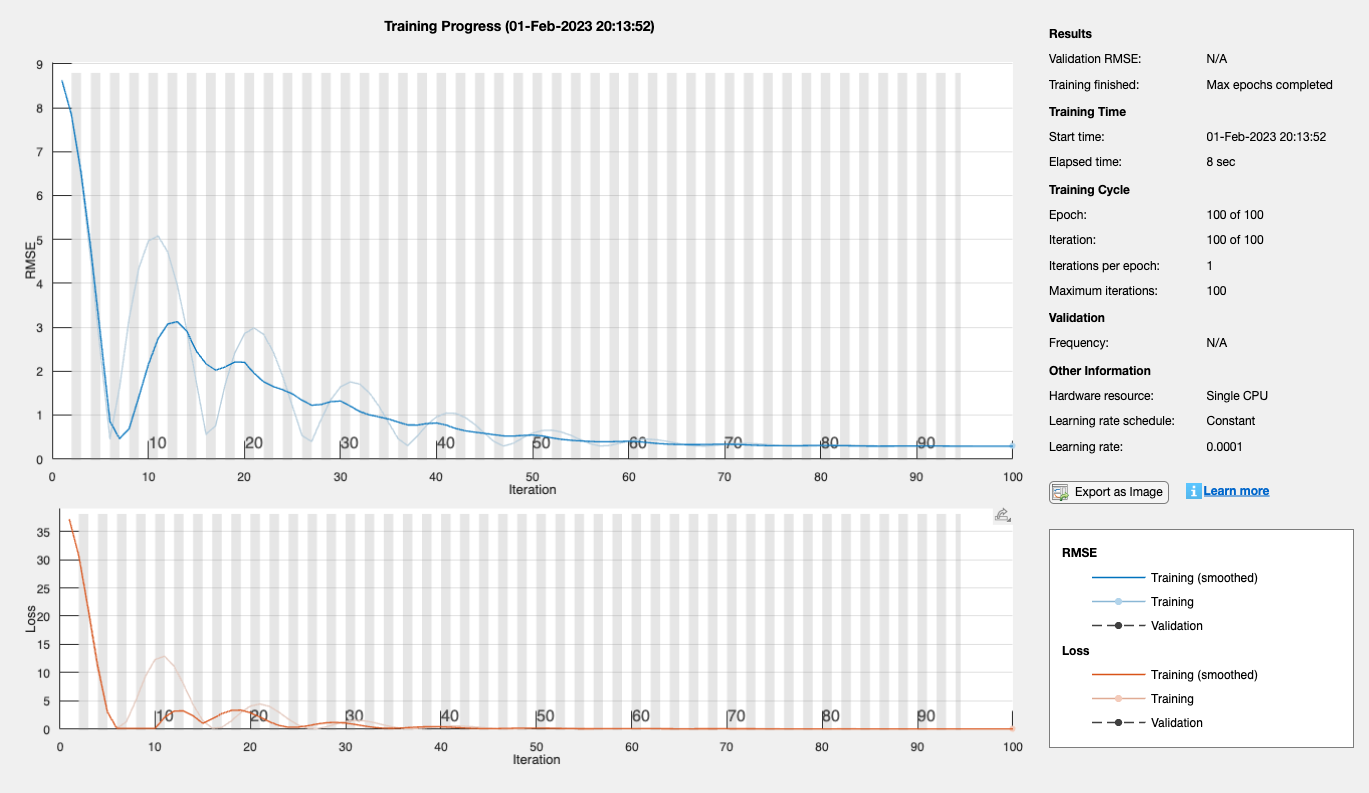

net = trainNetwork(x,y,layers,options);

*Figure 1.3. Training progress of the model.*

ymach = net.predict(x)

ymach = 1×100 single row vector
    0.5774    0.6768    0.7762    0.8755    0.9749    1.0743    1.1737    1.2731    1.3725    1.4718    1.5712    1.6706    1.7700    1.8694    1.9687    2.0681    2.1675    2.2669    2.3663    2.4657    2.5650    2.6644    2.7638    2.8632    2.9626    3.0619    3.1613    3.2607    3.3601    3.4595    3.5589    3.6582    3.7576    3.8570    3.9564    4.0558    4.1552    4.2545    4.3539    4.4533    4.5527    4.6521    4.7514    4.8508    4.9502    5.0496    5.1490    5.2484    5.3477    5.4471


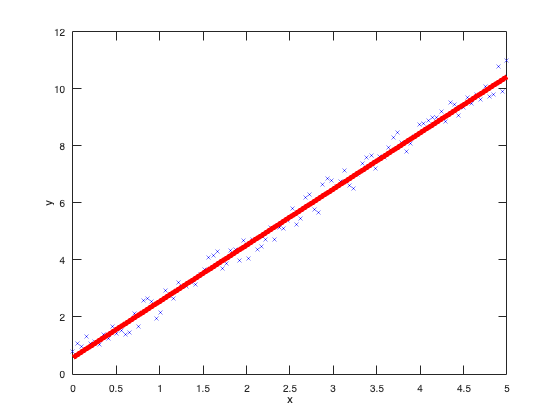

plot(x,y,'bx','MarkerSize',5)
hold on
plot(x,ymach, 'r', 'LineWidth',5)
xlabel('x'); ylabel('y');
hold off

% % Alternative 2
% net = fitnet(1,'trainscg');  %% algorithm is a scaled conjugate gradient
%                              %% with gradient descent ('traingd') and gradient descent with momentum ('traingdm')
%                              %% the fittings are non-linear
% % view(net);
% [net,tr] = train(net,x,y);
% % view(net);
% ypred = net(x);             %% solves for the predicted value given the x data
% perf = perform(net,x,y);    %% solves for the mean-squared error

## 1.3 Comparing human vs machine learning

As you can see from the code, it does not directly give out a numerical value for the slope and the y-intercept. It does, however, give out the best fit line to a certain margin of error of $y$ for a given value of $x$ based on the data. 

xtest = 3

xtest = 3

ytest = net.predict(xtest)

ytest = single
6.4807

yactual = slope*xtest + yintercept

yactual = 6.5144

error = 100*abs(yactual-ytest)/yactual

error = single
0.5181

Comparing with the actual value of 6.5, we have an error that is about 0.15%.

Why are we still solving for the error even if the calculations were performed by a computer? As you will soon learn, computers learn based on statistical techniques, which is why their guesses will not always be exact. To a computer, the result indicated by the red line in the graph is the most probable result from the given data.